% -- FLOW PROPERTIES -------------------------------------------
close all; clear all;
U_ref=28.272427879264484;  % Reference velocity [m/s]
P_ref=94009;               % Reference local static pressure [Pa]
Pt_ref=94450;              % Reference local stagnation pressure [Pa]
L_ref=1.85;                % Length of the walls at the test-section [m]
L_inlet=5.5;               % Length of the walls at the inlet [m]
Hyd_Diam_inlet=L_inlet;    % Hydraulic diamater [m]
A_ratio=(L_inlet/L_ref)^2; % Ratio of the contraction areas
U_guess=U_ref/A_ratio;     % Guess for the inlet's velocity

% -- FLUENT DATA -----------------------------------------------
U_r3=csvread("Data_Calibration/3.txt");
U_r31=csvread("Data_Calibration/31.txt");
U_r32=csvread("Data_Calibration/32.txt");
U_rI=csvread("Data_Calibration/Inter.txt");
P_rI=csvread("Data_Calibration/Inter_P.txt");
Pt_rI=csvread("Data_Calibration/Inter_Pt.txt");
U_rC=csvread("Data_Calibration/Calib.txt");
P_rC=csvread("Data_Calibration/Calib_P.txt");
Pt_rC=csvread("Data_Calibration/Calib_Pt.txt");

% -- CALIBRATION -----------------------------------------------
% Linear interpolation 
U_i=[3; 3.1; 3.2];
U_r=[mean(U_r3(3901:4000,2)); mean(U_r31(3901:4000,2)); mean(U_r32(3901:4000,2))];
a=U_r\U_i;
b=U_i(1)-U_r(1)*a;
U_inter=a*U_ref+b;

% Calibrated values (No pressure offset)
U_ref_sim=mean(U_rI(3901:4000,2));
P_ref_sim=mean(P_rI(3901:4000,2));
Pt_ref_sim=mean(Pt_rI(3901:4000,2));

% Pressure offset correction
P_offset=P_ref-P_ref_sim;

% Calibrated values with pressure correction
U_ref_cal=mean(U_rC(3901:4000,2));errU=abs(U_ref-U_ref_cal)*100/U_ref

errU = 0.0148

P_ref_cal=mean(P_rC(3901:4000,2));errP=abs(round(P_ref)-round(P_ref_cal))*100/P_ref

errP = 0

Pt_ref_cal=mean(Pt_rC(3901:4000,2));errPt=abs(round(Pt_ref)-round(Pt_ref_cal))*100/Pt_ref

errPt = 0

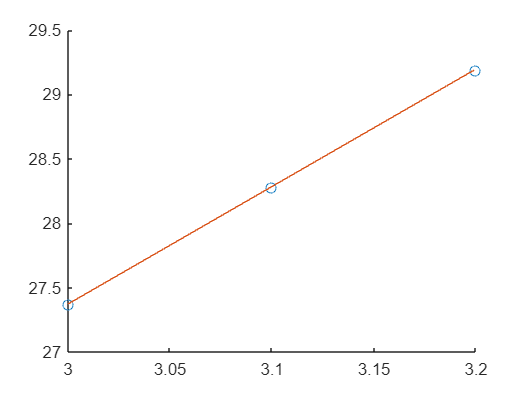


figure;
scatter(U_i,U_r);
hold on;
plot(a*(U_r(1):(U_r(end)-U_r(1))/99:U_r(end))+b,U_r(1):(U_r(end)-U_r(1))/99:U_r(end));
hold off;
xlim([U_i(1) U_i(end)]);